# Exercise 1

`Indentify the homogeneous matrix that maps from the base to the end-effector.`

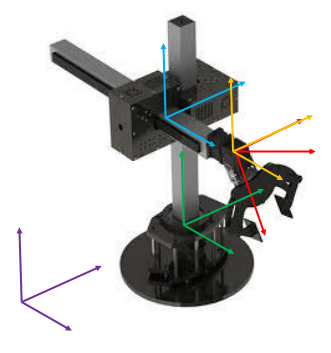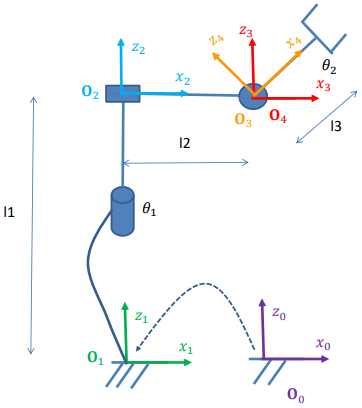

theta1 = pi/4;
l1 = 0.5;
l2 = 0.3;
theta2 = pi/3;
l3 = 0.2;

T10 = [rotz(rad2deg(theta1)) zeros(3, 1);
       zeros(1, 3) 1];

T21 = [eye(3) [0; 0; l1];
       zeros(1, 3) 1];

T32 = [eye(3) [l2; 0; 0];
       zeros(1, 3) 1];

T43 = [roty(rad2deg(theta2)) zeros(3, 1);
       zeros(1, 3) 1];

P0 = [0 0 0 1]';
P1 = T10*T21*[0 0 0 1]';
P2 = T10*T21*T32*[0 0 0 1]';
P3 = T10*T21*T32*T43*[l3 0 0 1]';

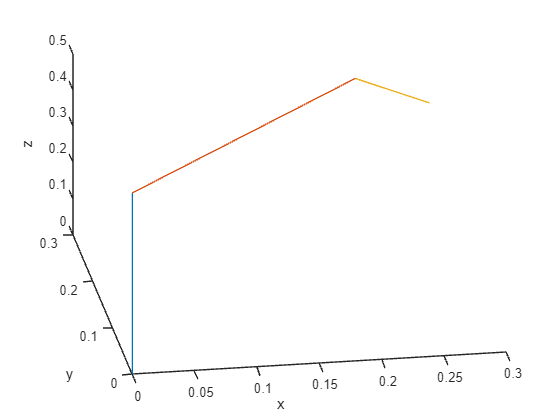

hold on;

plot3([P0(1) P1(1)], [P0(2) P1(2)], [P0(3), P1(3)]);
plot3([P1(1) P2(1)], [P1(2) P2(2)], [P1(3), P2(3)]);
plot3([P2(1) P3(1)], [P2(2) P3(2)], [P2(3), P3(3)]);
xlabel('x');
ylabel('y');
zlabel('z');

view([-9, 38]);